# 导弹追击

## 本文档建模存在bug

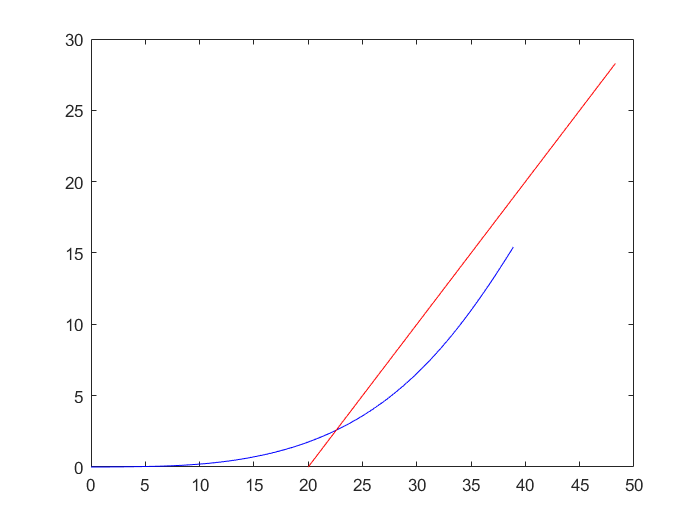

tspan = [0, 10]; 
y0 = [0 0];
option = odeset("RelTol",1e-4,"AbsTol",1e-8);
[t, y] = ode45(@df1, tspan, y0, option);
v_missile = 2;
Q = sqrt(2)*v_missile.*t;
P = 20 + Q;

plot(y(:,1), y(:,2), 'b-', P,Q,'r-');

## 由于函数只可回调，需要在外部寻找交点

Q = sqrt(2)/2*v_missile .*t;
P = 20 + Q;

l = length(t);
for v = 1:l
    if y(v,1) > P(v) && y(v,2) > Q(v)
        disp('触碰')
        result = [y(v,1), y(v,2), t(v)];
        break;
    end
end

触碰


function dy = df1(t, y)
    v_missile = 3;

    Q = sqrt(2)/2*v_missile*t;
    P = 20 + Q;
    com = 3*v_missile/(sqrt((P-(y(1))^2)+(Q-(y(2))^2)));
    dy = zeros(2, 1);
    dy(1) = com*(P-y(1));
    dy(2) = com*(Q-y(2));
end